## Condiciones iniciales

### Coordenadas y dimensiones de la placa

clear 
clc
syms beta theta Xa Za;
b=2.3;
h=0.675;
n=100;
xi=linspace(-0.5*h,0.5*h,n);
yi=linspace(-0.5*b,0.5*b,n);
zi=0.6*ones([1 n]);


### Coordenadas del punto fuera de la placa

Pix=h/2

Pix = 0.3375

Piy=b/2

Piy = 1.1500

zp=0.2

zp = 0.2000

### Variables independientes: $\beta ,\;\theta ,\;X_a ,\;Z_a$ 

beta=18;
theta=20;
Xa=00.3;
Za=0.2;

## Transformación de coordenadas de la placa superior y el punto en la placa 


$$T\left({x_i \;\;,\;y}_i \;,z_i \right)=\left({{\;\;x}_f \;\;,\;y}_f \;,{\;z}_f \right)$$


xf=Tx(xi,theta,Xa);
yf=Ty(yi,beta);
zf=Tz(xi,yi,zi,theta,beta,Za);

Pfx=Tx(Pix,theta,Xa);
Pfy=Ty(Piy,beta);
Pfz=Tz(Pix,Piy,zi(1,1),theta,beta,Za);


## Análisis geométrico del punto P

- 3 puntos transformados. 

- Producto cruz entre los dos vectores. 

- Ecuación de la recta con la altura total del punto respecto a la placa "zp".

p1x=Tx(0,theta,Xa);
p1y=Ty(0,beta);
p1z=Tz(0,0,zi(1),theta,beta,Za);

p2x=Tx(0.5*h,theta,Xa);
p2y=Ty(0,beta);
p2z=Tz(0.5*h,0,zi(1),theta,beta,Za);

p3x=Tx(0,theta,Xa);
p3y=Ty(0.5*b,beta);
p3z=Tz(0,0.5*b,zi(1),theta,beta,Za);

p1=[p1x p1y p1z];
p2=[p2x p2y p2z];
p3=[p3x p3y p3z];
n=cross(p2-p1,p3-p1)./norm(cross(p2-p1,p3-p1));
s=linspace(0,zp,100);

Pi=[Pfx Pfy Pfz];
P=zp*n+Pi

P =     0.5517    1.0353    1.4505


## Gráficas de placa superior y P

### Gráfica 3-D

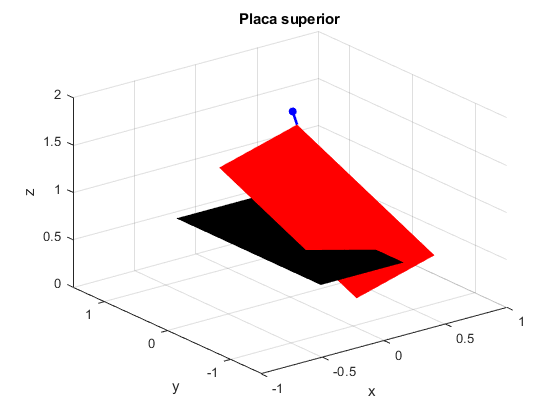

[X,Y] = meshgrid(xi,yi);
Z = zi.*ones(size(X));
[X2,Y2]=meshgrid(xf,yf);
Z2=Tz(X,Y,zi,theta,beta,Za);
surf(X,Y,Z,"EdgeColor","none","FaceColor","k")
hold on
surf(X2,Y2,Z2,"EdgeColor","none","FaceColor","r")
plot3(s.*n(1)+Pfx,s.*n(2)+Pfy,s.*n(3)+Pfz,"b","LineWidth",2)
scatter3(P(1),P(2),P(3),"b",'filled')
hold off
xlim([-1 1])
ylim([-1.5 1.5])
zlim([0 2])
xlabel("x")
ylabel("y")
zlabel("z")
title("Placa superior")

### Vista Lateral

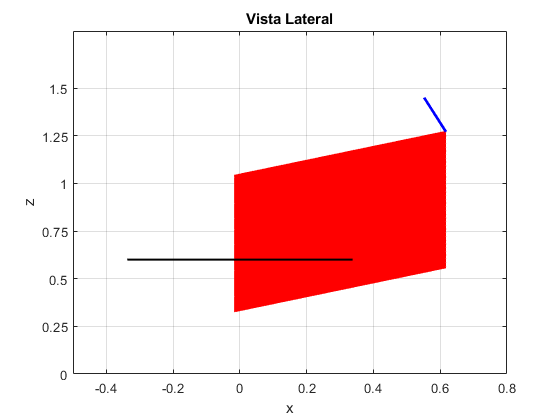

for i=1:length(X)
    plot(X(i,:),Z(i,:),"k","LineWidth",1.5)
    plot(X2(i,:),Z2(i,:),"r","LineWidth",1.5)
    hold on
end
plot(s.*n(1)+Pfx,s.*n(3)+Pfz,"b","LineWidth",2)
hold off
title("Vista Lateral")
xlabel("x")
ylabel("z")
xlim([-0.5 0.8])
ylim([0 1.8])
yticks(0:0.25:1.5)
grid on

### Vista frontal

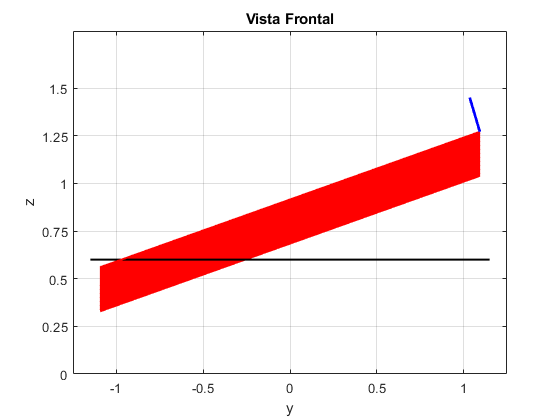

for i=1:length(Y)
    plot(Y(:,i),Z(:,i),"k","LineWidth",1.5)
    plot(Y2(:,i),Z2(:,i),"r","LineWidth",1.5)
    hold on
end
plot(s.*n(2)+Pfy,s.*n(3)+Pfz,"b","LineWidth",2)
hold off
title("Vista Frontal")
xlabel("y")
ylabel("z")
xlim([-1.25 1.25])
ylim([0 1.8])
yticks(0:0.25:1.5)
grid on

## Funciones

function [xf] = Tx(xi,theta,Xa)
    xf= xi*cosd(theta)+Xa;
end

function [yf] = Ty(yi,beta)
    yf= yi*cosd(beta);
end

function [zf] = Tz(xi,yi,zi,theta,beta,Za)
    zf= xi*sind(theta)+yi*sind(beta)+zi+Za;
end


